**Region Growing Method Notebook**

**Kuan-Min Lee**

**Region Growing Method:**

**Basic Theorem explanation:**

Region growing is a procedure that **group pixels or subregions into large regions.**

**Relative MATLAB function:**

activecontour(Image, mask,n,method);

**Active Contour Algorithm:**

**Algorithm Process:**

- Initialize the boundary (**active contour) in a auto-, semi-auto-, or manually way**

- **Move contours based on Energy minimization (ad-hoe energy equation (need more study)), or Partial differential equations**

- Contour stops moving

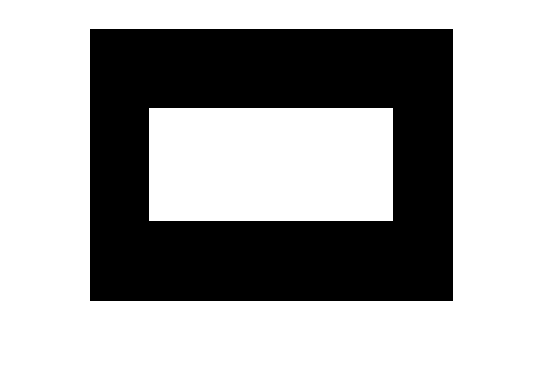

clear all
car_img=imread("car.jpg"); 
car_img_BW=rgb2gray(car_img);
mask=zeros(size(car_img_BW)); % create mask matrix 
mask(80:end-80, 60:end-60)=1;
imshow(mask)

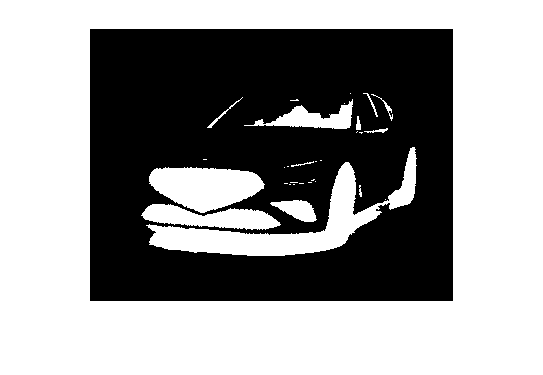

outcome=activecontour(car_img_BW,mask,500);
imshow(outcome)

**Testing on the image with complicated structures:**

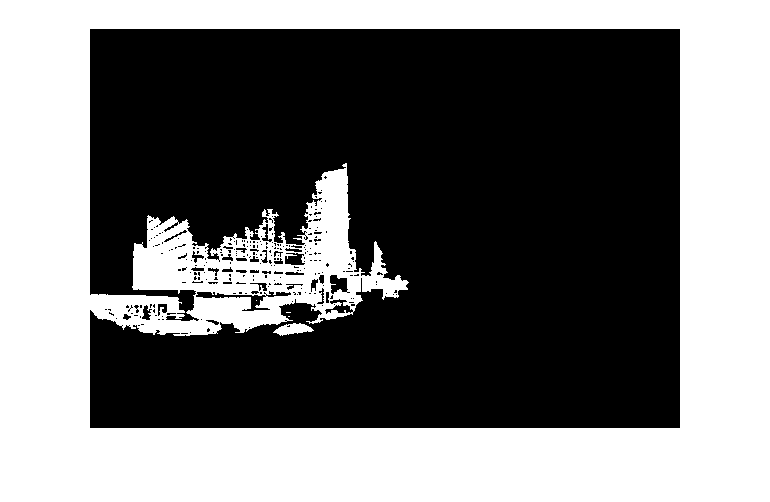

color_map=imread("google-maps-how-to-get-street-view-google-maps-2421144.jpg"); % read in sample color image
BW_map=rgb2gray(color_map); % convert it to grayscale
mask=zeros(size(BW_map)); 
mask(266:end-100, 118:200)=1;
outcome=activecontour(BW_map,mask,500);
imshow(outcome)

**Pros and Cons:**

**Pros:**

- **Good for edge detection for small objects or very obious objects in the image**

- **Contour can be improved **

**Cons:**

- **Hard to define mask in complicated structures**

- **Only generate the contours inside the initial region**

- **Initial contour guess is critical**